% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 8 Project: Package Delivery Time Estimator 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Define distance values (miles) 
d = 0:1:40; 
 
% ---------------------------- 
% Choose realistic parameters 
 
speed = 30; % miles per hour 
handling = 10; % minutes (fixed handling time) 
 
% Convert speed to minutes per mile 
m = 60 / speed; % minutes per mile 
b = handling; % intercept (handling time) 
 
% ---------------------------- 
% Time model 
T = m*d + b; 
 
% ---------------------------- 
% Create interpretation labels 
labels = strings(length(d),1); 
 
for i = 1:length(d) 
if T(i) < 30 
labels(i) = "short"; 
elseif T(i) < 60 
labels(i) = "medium"; 
else 
labels(i) = "long"; 
end 
end 
 
% ---------------------------- 
% Create table 
Table = table(d', T', labels, 'VariableNames', {'Distance_miles','Time_minutes','Category'}); 
 
disp('Delivery Time Table:'); 

Delivery Time Table:


disp(Table(1:15,:)); % show first 15 rows 

    Distance_miles    Time_minutes    Category
    ______________    ____________    ________

           0               10         "short" 
           1               12         "short" 
           2               14         "short" 
           3               16         "short" 
           4               18         "short" 
           5               20         "short" 
           6               22         "short" 
           7               24         "short" 
           8               26         "short" 
           9               28         "short" 
          10               30         "medium"
          11               32         "medium"
          12               34         "medium"
          13               36         "medium"
          14               38         "medium"



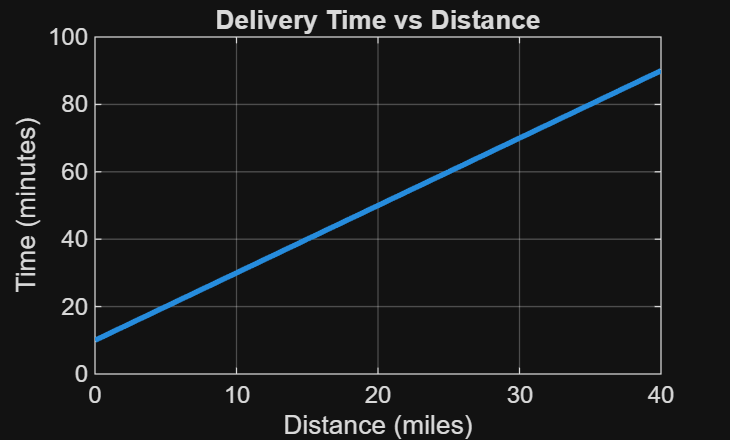

 
% ---------------------------- 
% Plot time vs distance 
figure; 
plot(d, T, 'LineWidth', 2); 
 
title('Delivery Time vs Distance'); 
xlabel('Distance (miles)'); 
ylabel('Time (minutes)'); 
grid on; 